clear

# India-Pakistan Arms Race Carrying Capacity Model

### Data Preprocessing

First we will import the data from Expenditure.csv and ExpenditurePercent.csv into separate tables. These csv files can be found at:

- Absolute spending: [https://data.worldbank.org/indicator/MS.MIL.XPND.CD](https://data.worldbank.org/indicator/MS.MIL.XPND.CD)

- Percent of GDP: [https://data.worldbank.org/indicator/MS.MIL.XPND.GD.ZS](https://data.worldbank.org/indicator/MS.MIL.XPND.GD.ZS) 

We will extract from each of these tables the countries that have military expenditure data available from 1960-2020 with no missing values.

dataLines = [5, Inf];
timeline = 1960:2020;
yearNames = string(timeline);

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 65, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["CountryName", "CountryCode", "IndicatorName", "IndicatorCode", yearNames];
opts.VariableTypes = ["string", "string", "categorical", "categorical", repelem("double",61)];
opts.VariableNamingRule = 'preserve';

% https://data.worldbank.org/indicator/MS.MIL.XPND.CD 
expenseRaw = readtable("Expenditure.csv", opts);

%drop first row & extra cols
expenseRaw(1,:) = [];
expenseRaw(:,[3, 4, end]) = [];

%sort by country name
expenseRaw = sortrows(expenseRaw,"CountryName","ascend");

%divide all doubles by 1e9 to get numbers in billions USD
expenseNum = expenseRaw{:,vartype('numeric')};
expenseNum = expenseNum/1e9;
%index of empty rows
idx = all(isnan(expenseNum),2); %column logical
expenseRaw{:,vartype('numeric')} = expenseNum;

expenseRaw = expenseRaw(~idx,:); %drop all empty rows

%take countries with data for all years
expenseFull = expenseRaw;
expenseNum = expenseFull{:,vartype('numeric')};
%index of all full rows
idx = all(~isnan(expenseNum),2);
expenseFull = expenseFull(idx,:);

%interpolate missing values
%expenseRaw{:,vartype('numeric')} = fillmissing(expenseRaw{:,vartype('numeric')},'pchip',2); 

%% Set up the Import Options and import the data of military expenditure as a % of GDP
opts = delimitedTextImportOptions("NumVariables", 65, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["CountryName", "CountryCode", "IndicatorName", "IndicatorCode", yearNames];
opts.VariableTypes = ["string", "string", "categorical", "categorical", repelem("double",61)];
opts.VariableNamingRule = 'preserve';

percentRaw = readtable("ExpenditurePercent.csv", opts);

%drop first row & extra cols
percentRaw(1,:) = [];
percentRaw(:,[3, 4, end]) = [];

%sort by country name
percentRaw = sortrows(percentRaw,"CountryName","ascend");

%divide all doubles by 100 to get percent on a scale from 0-1
percentNum = percentRaw{:,vartype('numeric')};
percentNum = percentNum/100;
%index of empty rows
idx = all(isnan(percentNum),2); %column logical
percentRaw{:,vartype('numeric')} = percentNum;

percentRaw = percentRaw(~idx,:); %drop all empty rows

%take countries with data for all years
percentFull = percentRaw;
percentNum = percentFull{:,vartype('numeric')};
%index of all full rows
idx = all(~isnan(percentNum),2);
percentFull = percentFull(idx,:);


%percentRaw{:,vartype('numeric')} = fillmissing(percentRaw{:,vartype('numeric')},'pchip',2);


%clear variables that will not be used again
clear opts idx percentNum expenseNum

### Military Spending

Fit data for Inida's and Pakistan's expenditure to the carrying capacity model.

%extract data for India and find the derivatives of the list 
indiaIdx = expenseFull.CountryName == 'India';
india = expenseFull{indiaIdx, vartype('numeric')};
indiaDer = derivative(india,1,2);

%extract data for Pakistan and find the derivatives of the list 
pakiIdx = expenseFull.CountryName == 'Pakistan';
paki = expenseFull{pakiIdx, vartype('numeric')};
pakiDer = derivative(paki,1,2);


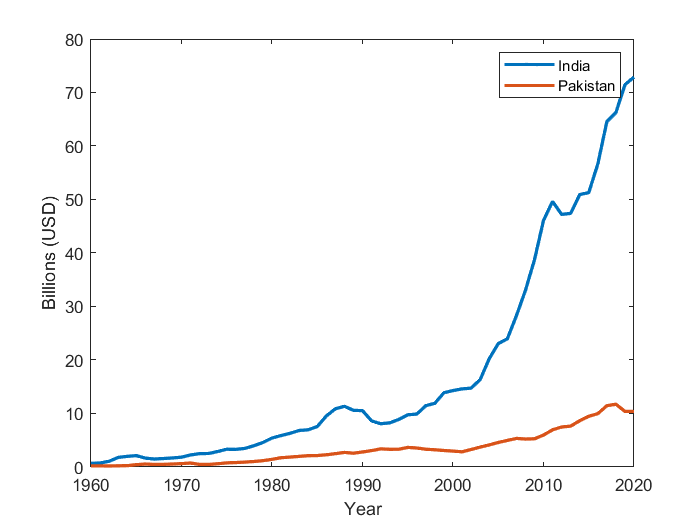

%plot data to help visualize trends

plot(timeline,india,'LineWidth',2)
hold on
plot(timeline,paki,'LineWidth',2)
%title("Military Spending by Year")
xlabel("Year")
ylabel("Billions (USD)")
legend("India", "Pakistan")
hold off

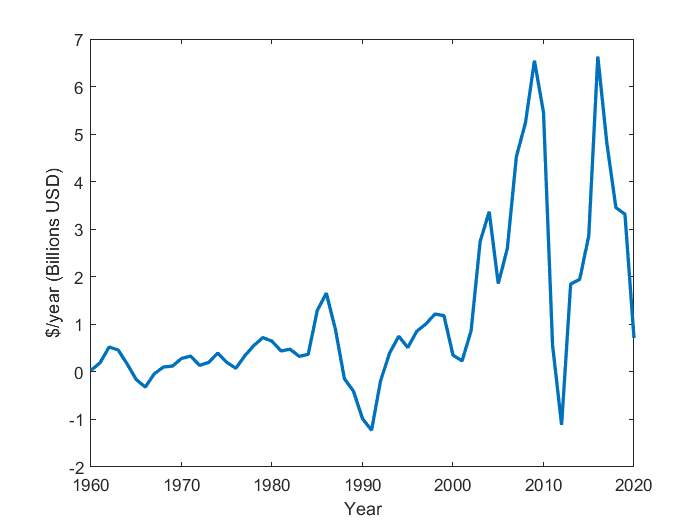


plot(timeline,indiaDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

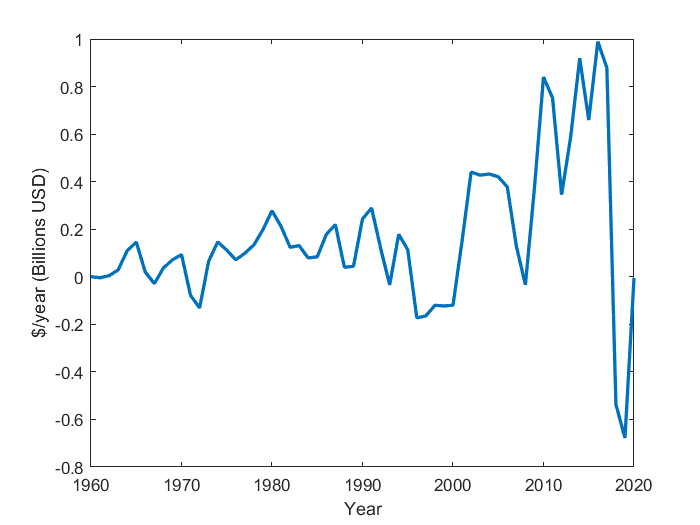


plot(timeline,pakiDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

%fit data to carryingCap model
[india_fit, india_gof] = carryingCapFit(india,paki,indiaDer,100);
[paki_fit, paki_gof] = carryingCapFit(paki,india,pakiDer,100);

indiaParam = coeffvalues(india_fit); %extract parameters
indiaInt = confint(india_fit); %confidence intervals
dIdt = @(I,P) carryingCap(I,P,indiaParam(1),indiaParam(2),indiaParam(3),indiaParam(4));

pakiParam = coeffvalues(paki_fit); %extract parameters
pakiInt = confint(paki_fit); %confidence intervals
dPdt = @(P,I) carryingCap(P,I,pakiParam(1),pakiParam(2),pakiParam(3),pakiParam(4));

%system of linear equations defing the fitted carryingCap model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%find fixed points of the fitted system
clear x y
syms x y;
[xFP,yFP] = solve(dIdt(x,y)==0,dPdt(y,x)==0);

%Find the eigenvalues of the linearized system using the Jacobian
jac = jacobian([dIdt(x,y),dPdt(y,x)], [x y]);
eigval = zeros(2,length(xFP));
for i=1:length(xFP)
    temp = subs(jac,[x y],[xFP(i) yFP(i)]);
    eigval(:,i) = eig(temp);
end
eigval = eigval';

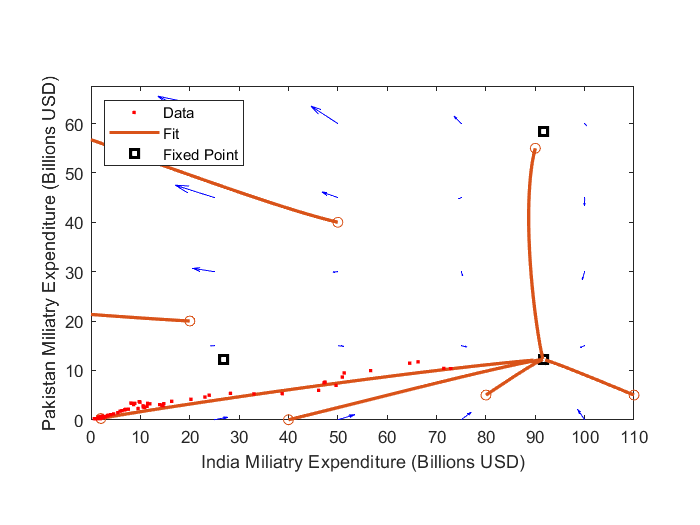

%plotting arrows
x1 = linspace(0,100,5);
y1 = linspace(0,60,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India Miliatry Expenditure (Billions USD)")
ylabel("Pakistan Miliatry Expenditure (Billions USD)")
axis tight equal;
hold on


%plot fixed points in domain
fixedPoint = plot(xFP(2),yFP(2),'ks','LineWidth',2);
plot(xFP(3),yFP(3),'ks','LineWidth',2)
plot(xFP(4),yFP(4),'ks','LineWidth',2);

%plotting various trajectories
[~,ys] = ode45(f,[0;50],[40,0]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[110;5]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;50],[80;5]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;4],[20;20]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;4.7],[50;40]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;50],[90;55]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;50],[india(5),paki(5)]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%plot data
%plot(india(1),paki(1),'r.','LineWidth',2) %starting point
%plot(india(end),paki(end),'gs','LineWidth',2) %ending point
d = plot(india,paki,'r.');
%plot(indiaFP,pakiFP,'ks','LineWidth',2)


%title("Carrying Capacity Model")
legend([d d2, fixedPoint],"Data","Fit","Fixed Point","Location",'northwest')
xlim([0 110])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(india_gof.sse) + newline + ...
    "* R-Square " + num2str(india_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(india_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 94.1515
* R-Square 0.5023
* Root Mean Square Error 1.2852


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(paki_gof.sse) + newline + ...
    "* R-Square " + num2str(paki_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(paki_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 4.3286
* R-Square 0.23015
* Root Mean Square Error 0.27557


%see parameters
disp("xmax = " + num2str(indiaParam(1)) + " within 95% confidence of " + num2str(indiaInt(:,1)') + newline + ...
    "k = " + num2str(indiaParam(2)) + " within 95% confidence of " + num2str(indiaInt(:,2)') + newline + ...
    "a = " + num2str(indiaParam(3)) + " within 95% confidence of " + num2str(indiaInt(:,3)') + newline + ...
    "g = " + num2str(indiaParam(4)) + " within 95% confidence of " + num2str(indiaInt(:,4)') + newline + ...
    "ymax = " + num2str(pakiParam(1)) + " within 95% confidence of " + num2str(pakiInt(:,1)') + newline + ...
    "k' = " + num2str(pakiParam(2)) + " within 95% confidence of " + num2str(pakiInt(:,2)') + newline + ...
    "a' = " + num2str(pakiParam(3)) + " within 95% confidence of " + num2str(pakiInt(:,3)') + newline + ...
    "g' = " + num2str(pakiParam(4))+ " within 95% confidence of " + num2str(pakiInt(:,4)'))

xmax = 91.5738 within 95% confidence of 71.34479      111.8028
k = -0.51733 within 95% confidence of -1.1626     0.12792
a = -0.24058 within 95% confidence of -0.37273    -0.10843
g = -0.12323 within 95% confidence of -0.78425      0.5378
ymax = 12.2122 within 95% confidence of 9.83373      14.5906
k' = 0.032724 within 95% confidence of 0.0041552    0.061294
a' = 0.051165 within 95% confidence of -0.10105     0.20338
g' = -0.0074416 within 95% confidence of -0.15675     0.14186


disp("Fixed points are found at:" + newline + ...
    "x* = " + num2str(double(xFP)) + ", y* = " + num2str(double(yFP)) + ", with eigenvalues: " + num2str(eigval))

    "Fixed points are found at:↵x* = -0.531364, y* = -0.485295, with eigenvalues:  0.030534     0.15824"
    "Fixed points are found at:↵x* =    26.773, y* =   12.2122, with eigenvalues: -0.019968     0.17024"
    "Fixed points are found at:↵x* =   91.5738, y* =   58.4237, with eigenvalues:  0.090824     0.19361"
    "Fixed points are found at:↵x* =   91.5738, y* =   12.2122, with eigenvalues:  -0.19361    -0.17024"



### Military Spending (Smoothed)

We can try to improve the fit by smoothing the data with a rolling average.

indiaAve = movmean(india,5);
indiaAveDer = derivative(indiaAve,1,2);

pakiAve = movmean(paki,5);
pakiAveDer = derivative(pakiAve,1,2);

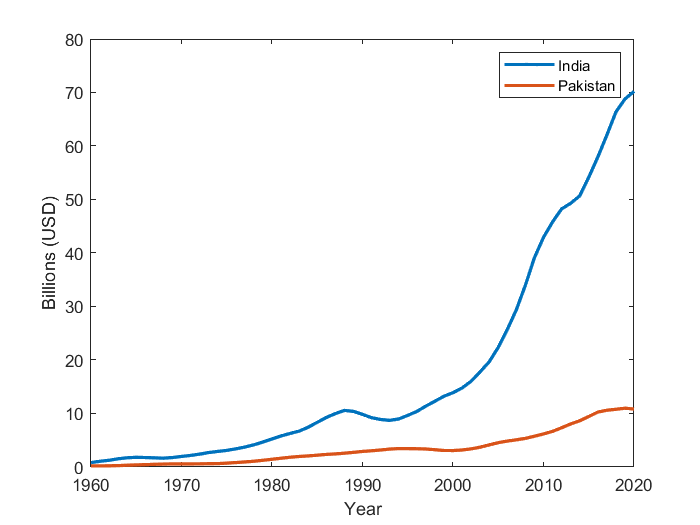

%plot data to help visualize trends

plot(timeline,indiaAve,'LineWidth',2)
hold on
plot(timeline,pakiAve,'LineWidth',2)
%title("Military Spending by Year (Smoothed)")
xlabel("Year")
ylabel("Billions (USD)")
legend("India", "Pakistan")
hold off

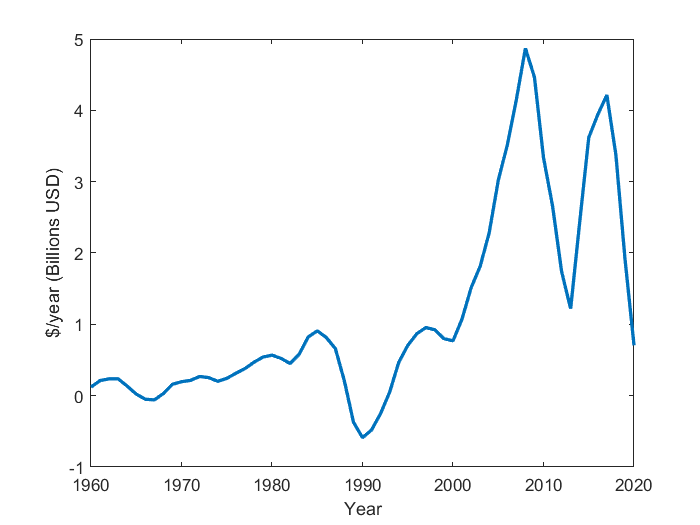


plot(timeline,indiaAveDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

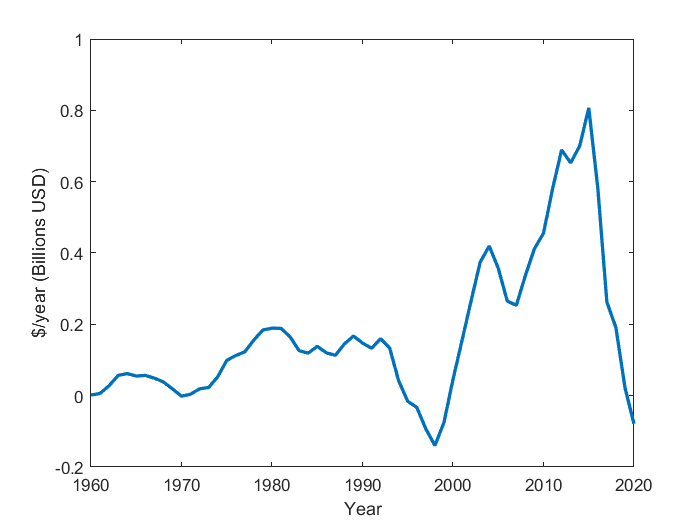


plot(timeline,pakiAveDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

%fit data to carryingCap model
[indiaAve_fit, indiaAve_gof] = carryingCapFit(indiaAve,pakiAve,indiaAveDer,100);
[pakiAve_fit, pakiAve_gof] = carryingCapFit(pakiAve,indiaAve,pakiAveDer,100);

indiaAveParam = coeffvalues(indiaAve_fit); %extract parameters
indiaAveInt = confint(indiaAve_fit); %confidence intervals
dIdt = @(I,P) carryingCap(I,P,indiaAveParam(1),indiaAveParam(2),indiaAveParam(3),indiaAveParam(4));

pakiAveParam = coeffvalues(pakiAve_fit); %extract parameters
pakiAveInt = confint(pakiAve_fit); %confidence intervals
dPdt = @(P,I) carryingCap(P,I,pakiAveParam(1),pakiAveParam(2),pakiAveParam(3),pakiAveParam(4));

%system of linear equations defing the fitted carryingCap model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%find fixed points of the fitted system
clear x y
syms x y;
[xFP,yFP] = solve(dIdt(x,y)==0,dPdt(y,x)==0);

%Find the eigenvalues of the linearized system using the Jacobian
jac = jacobian([dIdt(x,y),dPdt(y,x)], [x y]);
eigval = zeros(2,length(xFP));
for i=1:length(xFP)
    temp = subs(jac,[x y],[xFP(i) yFP(i)]);
    eigval(:,i) = eig(temp);
end
eigval = eigval';

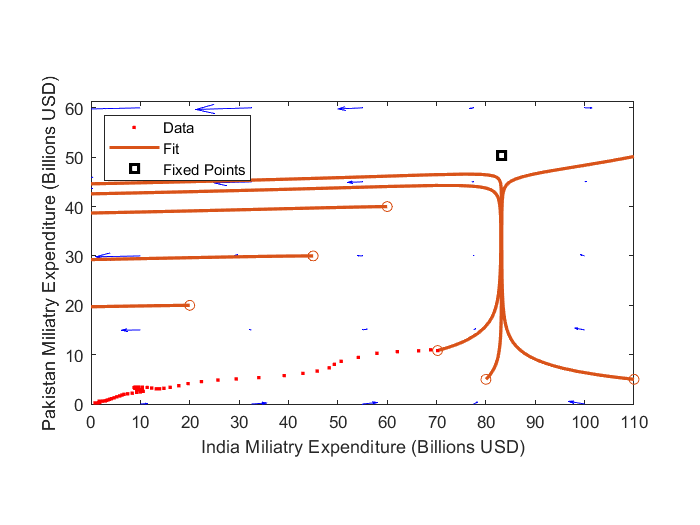

%plotting arrows
x1 = linspace(10,100,5);
y1 = linspace(0,60,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India Miliatry Expenditure (Billions USD)")
ylabel("Pakistan Miliatry Expenditure (Billions USD)")
axis tight equal;
hold on

%plot fixed points in domain
fixedPoint = plot(xFP(2),yFP(2),'ks','LineWidth',2);

%plotting various trajectories
%[~,ys] = ode45(f,[0;10],[2,0.5]);
%d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
%plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;173],[110;5]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;182],[80;5]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;2.3],[20;20]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;5.5],[45;30]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;7],[60;40]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;142.5],[indiaAve(end);pakiAve(end)]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point


%plot data
%plot(indiaAve(1),pakiAve(1),'r.','LineWidth',2) %starting point
%plot(indiaAve(end),pakiAve(end),'gs','LineWidth',2) %ending point
d = plot(indiaAve,pakiAve,'r.');
%plot(indiaAveFP,pakiAveFP,'ks','LineWidth',2)

%title("Carrying Capacity Model (Smoothed)")
legend([d d2 fixedPoint],"Data","Fit","Fixed Points","Location",'northwest')
xlim([0 110])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaAve_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaAve_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaAve_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 28.6874
* R-Square 0.75341
* Root Mean Square Error 0.70943


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiAve_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiAve_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiAve_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 1.6775
* R-Square 0.35639
* Root Mean Square Error 0.17155


%see parameters
disp("xmax = " + num2str(indiaAveParam(1)) + " within 95% confidence of " + num2str(indiaAveInt(:,1)') + newline + ...
    "k = " + num2str(indiaAveParam(2)) + " within 95% confidence of " + num2str(indiaAveInt(:,2)') + newline + ...
    "a = " + num2str(indiaAveParam(3)) + " within 95% confidence of " + num2str(indiaAveInt(:,3)') + newline + ...
    "g = " + num2str(indiaAveParam(4)) + " within 95% confidence of " + num2str(indiaAveInt(:,4)') + newline + ...
    "ymax = " + num2str(pakiAveParam(1)) + " within 95% confidence of " + num2str(pakiAveInt(:,1)') + newline + ...
    "k' = " + num2str(pakiAveParam(2)) + " within 95% confidence of " + num2str(pakiAveInt(:,2)') + newline + ...
    "a' = " + num2str(pakiAveParam(3)) + " within 95% confidence of " + num2str(pakiAveInt(:,3)') + newline + ...
    "g' = " + num2str(pakiAveParam(4))+ " within 95% confidence of " + num2str(pakiAveInt(:,4)'))

xmax = 83.1673 within 95% confidence of 74.8742      91.4605
k = -0.68683 within 95% confidence of -1.0862    -0.28742
a = -0.28092 within 95% confidence of -0.36205     -0.1998
g = -0.10163 within 95% confidence of -0.47938     0.27611
ymax = 41030.0026 within 95% confidence of -239755561.5718       239837621.577
k' = 0.0085224 within 95% confidence of -0.0072356     0.02428
a' = 0.015613 within 95% confidence of -0.057826    0.089052
g' = 0.076847 within 95% confidence of -0.012746     0.16644


disp("Fixed points are found at:" + newline + ...
    "x* = " + num2str(double(xFP)) + ", y* = " + num2str(double(yFP)) + ", with eigenvalues: " + num2str(eigval))

    "Fixed points are found at:↵x* = 100315.2058, y* =  41030.0026, with eigenvalues:    -338.562  -0.005225575"
    "Fixed points are found at:↵x* = 83.16733784, y* =  50.3194316, with eigenvalues: -0.01559371     0.1358583"
    "Fixed points are found at:↵x* = -37.0493916, y* = -15.3016327, with eigenvalues: 0.005512435     0.3849348"
    "Fixed points are found at:↵x* = 83.16733784, y* =  41030.0026, with eigenvalues:  0.01559371       338.562"



The dynamics of the sytem remained unchanged by smoothing the data.

### Military Spending (%) (Smoothed Data)

Analyze India's and Pakistan's military spending as a percent of GDP.

%extract data for India and find the derivatives of the list 
indiaIdx = percentFull.CountryName == 'India';
indiaPer = movmean(percentFull{indiaIdx, vartype('numeric')},5);
indiaPerDer = derivative(indiaPer,1,2);

%extract data for Pakistan and find the derivatives of the list 
pakiIdx = percentFull.CountryName == 'Pakistan';
pakiPer = movmean(percentFull{pakiIdx, vartype('numeric')},5);
pakiPerDer = derivative(pakiPer,1,2);

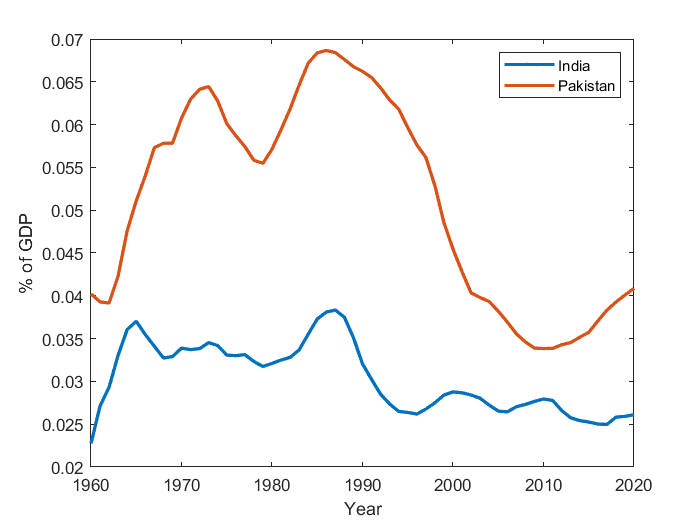

%plot data to help visualize trends

plot(timeline,indiaPer,'LineWidth',2)
hold on
plot(timeline,pakiPer,'LineWidth',2)
%title("Military Spending by Year")
xlabel("Year")
ylabel("% of GDP")
legend("India", "Pakistan")
hold off

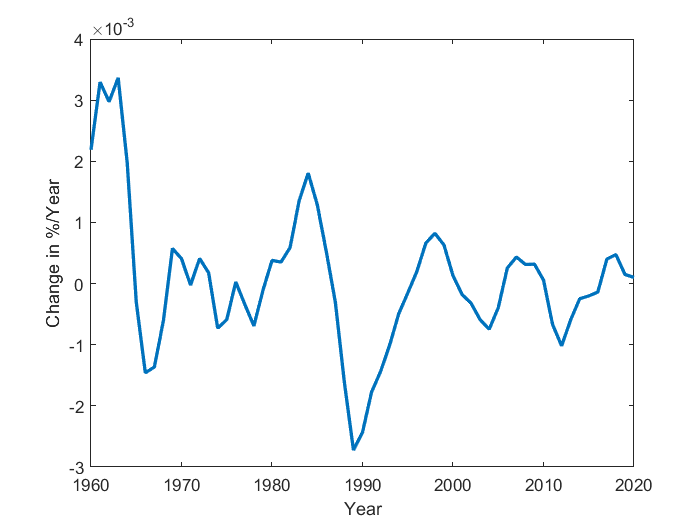


plot(timeline,indiaPerDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("Change in %/Year")

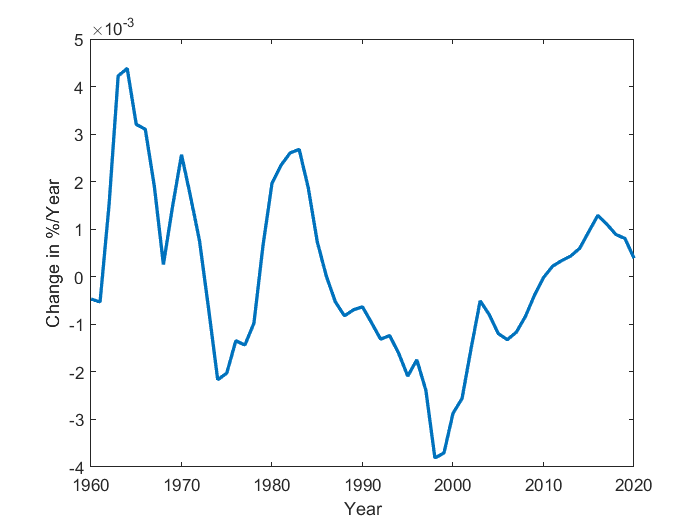


plot(timeline,pakiPerDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("Change in %/Year")

%fit data to carryingCap model
[indiaPer_fit, indiaPer_gof] = carryingCapFit(indiaPer,pakiPer,indiaPerDer,0.15);
[pakiPer_fit, pakiPer_gof] = carryingCapFit(pakiPer,indiaPer,pakiPerDer,0.15);

indiaPerParam = coeffvalues(indiaPer_fit); %extract parameters
indiaPerInt = confint(indiaPer_fit); %confidence intervals
dIdt = @(I,P) carryingCap(I,P,indiaPerParam(1),indiaPerParam(2),indiaPerParam(3),indiaPerParam(4));

pakiPerParam = coeffvalues(pakiPer_fit); %extract parameters
pakiPerInt = confint(pakiPer_fit); %confidence intervals
dPdt = @(P,I) carryingCap(P,I,pakiPerParam(1),pakiPerParam(2),pakiPerParam(3),pakiPerParam(4));

%system of linear equations defing the fitted carryingCap model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%find fixed points of the fitted system
clear x y
syms x y;
[xFP,yFP] = solve(dIdt(x,y)==0,dPdt(y,x)==0);

%Find the eigenvalues of the linearized system using the Jacobian
jac = jacobian([dIdt(x,y),dPdt(y,x)], [x y]);
eigval = zeros(2,length(xFP));
for i=1:length(xFP)
    temp = subs(jac,[x y],[xFP(i) yFP(i)]);
    eigval(:,i) = eig(temp);
end
eigval = eigval';

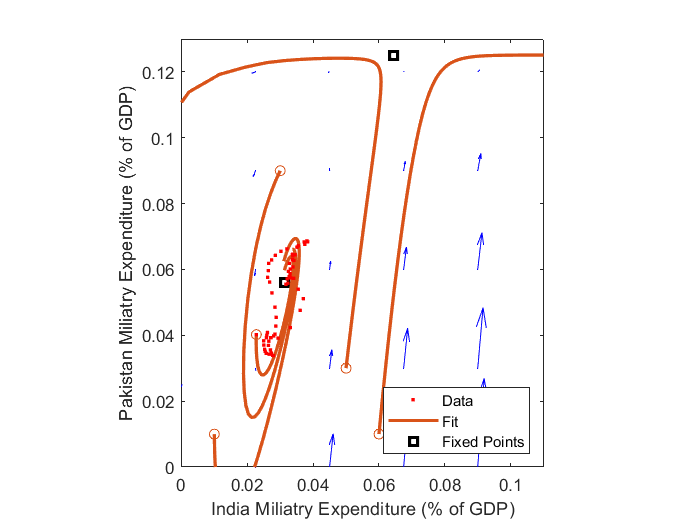

%plotting arrows
x1 = linspace(0,0.09,5);
y1 = linspace(0,0.12,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India Miliatry Expenditure (% of GDP)")
ylabel("Pakistan Miliatry Expenditure (% of GDP)")
axis tight equal;
hold on


%plot fixed points in domain
fixedPoint = plot(xFP(1),yFP(1),'ks','LineWidth',2);
plot(xFP(2),yFP(2),'ks','LineWidth',2)
plot(xFP(3),yFP(3),'ks','LineWidth',2)
plot(xFP(4),yFP(4),'ks','LineWidth',2)

%plotting various trajectories
[~,ys] = ode45(f,[0;90],[indiaPer(1),pakiPer(1)]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;90],[0.01;0.01]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;90],[0.03;0.09]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;140],[0.05;0.03]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;60],[0.06;0.01]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%plot data
%plot(indiaPer(1),pakiPer(1),'r.','LineWidth',2) %starting point
%plot(indiaPer(end),pakiPer(end),'gs','LineWidth',2) %ending point
d = plot(indiaPer,pakiPer,'r.');
%plot(indiaPerFP,pakiPerFP,'ks','LineWidth',2)


%title("Carrying Capacity Model (Smoothed)")
legend([d d2 fixedPoint],"Data","Fit","Fixed Points","Location","southeast")
xlim([0 0.11])
ylim([0 0.13])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaPer_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaPer_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaPer_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 7.7138e-05
* R-Square 0.058849
* Root Mean Square Error 0.0011633


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiPer_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiPer_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiPer_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 0.00014152
* R-Square 0.28113
* Root Mean Square Error 0.0015757


%see parameters
disp("xmax = " + num2str(indiaPerParam(1)) + " within 95% confidence of " + num2str(indiaPerInt(:,1)') + newline + ...
    "k = " + num2str(indiaPerParam(2)) + " within 95% confidence of " + num2str(indiaPerInt(:,2)') + newline + ...
    "a = " + num2str(indiaPerParam(3)) + " within 95% confidence of " + num2str(indiaPerInt(:,3)') + newline + ...
    "g = " + num2str(indiaPerParam(4)) + " within 95% confidence of " + num2str(indiaPerInt(:,4)') + newline + ...
    "ymax = " + num2str(pakiPerParam(1)) + " within 95% confidence of " + num2str(pakiPerInt(:,1)') + newline + ...
    "k' = " + num2str(pakiPerParam(2)) + " within 95% confidence of " + num2str(pakiPerInt(:,2)') + newline + ...
    "a' = " + num2str(pakiPerParam(3)) + " within 95% confidence of " + num2str(pakiPerInt(:,3)') + newline + ...
    "g' = " + num2str(pakiPerParam(4))+ " within 95% confidence of " + num2str(pakiPerInt(:,4)'))

xmax = 0.33652 within 95% confidence of -43.7717      44.4447
k = -0.023957 within 95% confidence of -0.32571      0.2778
a = -0.05004 within 95% confidence of -0.71844     0.61836
g = -0.00023061 within 95% confidence of -0.0048615   0.0044003
ymax = 0.12514 within 95% confidence of -0.10149     0.35177
k' = 0.60385 within 95% confidence of -0.26384      1.4715
a' = 0.14503 within 95% confidence of -0.068273     0.35833
g' = -0.010856 within 95% confidence of -0.026867   0.0051557


disp("Fixed points are found at:" + newline + ...
    "x* = " + num2str(double(xFP)) + ", y* = " + num2str(double(yFP)) + ", with eigenvalues: " + num2str(eigval))

    "Fixed points are found at:↵x* = 0.031435, y* = 0.056033, with eigenvalues: -0.017361+0.057515i      -0.017361-0.057515i"
    "Fixed points are found at:↵x* =  0.33652, y* =   1.3263, with eigenvalues:  0.045067+0i                1.3921+0i       "
    "Fixed points are found at:↵x* = 0.064521, y* =  0.12514, with eigenvalues: -0.079562+0i              0.040446+0i       "
    "Fixed points are found at:↵x* =  0.33652, y* =  0.12514, with eigenvalues:   -1.3921+0i             -0.040446+0i       "



### Nuclear Arms Race

dataLines = [2, Inf];
filename = "number-of-nuclear-warheads-in-the-inventory-of-the-nuclear-powers.csv";
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Entity", "Code", "Year", "Count"];
opts.VariableTypes = ["categorical", "categorical", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Entity", "Code"], "EmptyFieldRule", "auto");

% Import the data
nukeRaw = readtable(filename, opts);

clear opts filename datalines

timelineNuke = 1998:2017;

%Pakistan's nukes
pakiIdx = nukeRaw.Entity == 'Pakistan' & nukeRaw.Year>=1998;
pakiNuke = nukeRaw.Count(pakiIdx);

%India's nukes during the cold war
indiaIdx = nukeRaw.Entity == 'India' & nukeRaw.Year>=1998;
indiaNuke = nukeRaw.Count(indiaIdx);

%change in nuclear stockpile with time
indiaNukeDer = derivative(indiaNuke,1,1);

pakiNukeDer = derivative(pakiNuke,1,1);

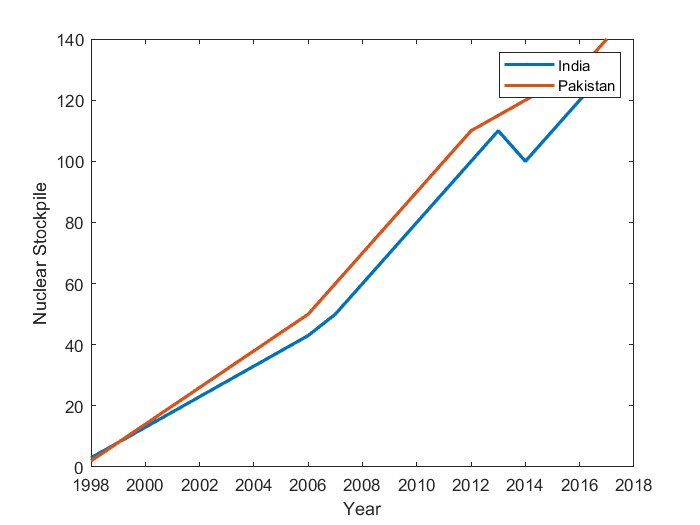

plot(timelineNuke,indiaNuke,"LineWidth",2);
hold on
plot(timelineNuke,pakiNuke,"LineWidth",2)
legend("India","Pakistan")
xlabel("Year")
ylabel("Nuclear Stockpile")
hold off

%fit data to carrying capacity model
[indiaNuke_fit, indiaNuke_gof] = carryingCapFit(indiaNuke,pakiNuke,indiaNukeDer,200);
[pakiNuke_fit, pakiNuke_gof] = carryingCapFit(pakiNuke,indiaNuke,pakiNukeDer,200);

indiaNukeParam = coeffvalues(indiaNuke_fit); %extract parameters
indiaNukeInt = confint(indiaNuke_fit); %confidence intervals
dINdt = @(I,P) carryingCap(I,P,indiaNukeParam(1),indiaNukeParam(2),indiaNukeParam(3),indiaNukeParam(4));

pakiNukeParam = coeffvalues(pakiNuke_fit); %extract parameters
pakiNukeInt = confint(pakiNuke_fit); %confidence intervals
dPNdt = @(P,I) carryingCap(P,I,pakiNukeParam(1),pakiNukeParam(2),pakiNukeParam(3),pakiNukeParam(4));

%system of linear equations defing the fitted carrying capacity model
f = @(t,X) [dINdt(X(1),X(2)); dPNdt(X(2),X(1))];

%find fixed points of the fitted system
clear x y
syms x y;
[xFP,yFP] = solve(dINdt(x,y)==0,dPNdt(y,x)==0);

%Find the eigenvalues of the linearized system using the Jacobian
jac = jacobian([dINdt(x,y),dPNdt(y,x)], [x y]);
eigval = zeros(2,length(xFP));
for i=1:length(xFP)
    temp = subs(jac,[x y],[xFP(i) yFP(i)]);
    eigval(:,i) = eig(temp);
end
eigval = eigval';

%plotting arrows
x1 = linspace(10,200,5);
y1 = linspace(0,200,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India's Nuclear Stockpile")
ylabel("Pakistan's Nuclear Stockpile")
axis tight equal;
hold on

%plot fixed points in domain
fixedPoint = plot(xFP(1),yFP(1),'ks','LineWidth',2);
plot(xFP(2),yFP(2),'ks','LineWidth',2)


%plotting various trajectories
[~,ys] = ode45(f,[0;63],[indiaNuke(1),pakiNuke(1)]); %63 years from 1998
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%[~,ys] = ode45(f,[0;20],[110,80]);
%plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
%plot(ys(1,1),ys(1,2),'bo') % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;10],[60,100]);

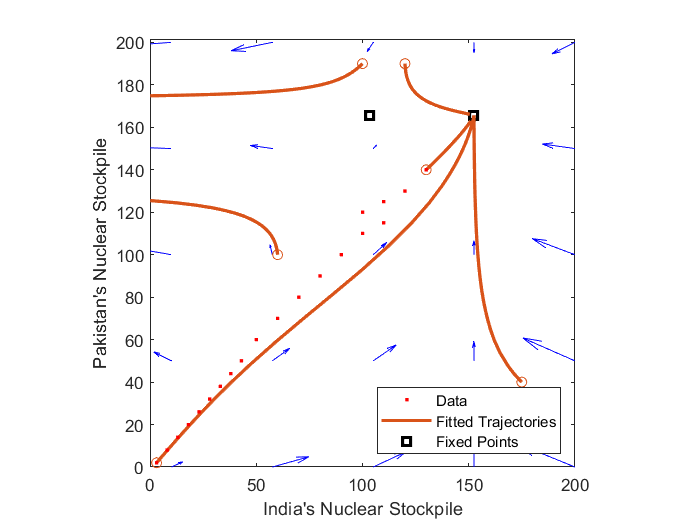

plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;5.7],[100,190]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;50],[175,40]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[120,190]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;12],[indiaNuke(end),pakiNuke(end)]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point


%plot data
%plot(indiaNuke(1),pakiNuke(1),'r.','LineWidth',2) %starting point
%plot(indiaNuke(end),pakiNuke(end),'gs','LineWidth',2) %ending point
d = plot(indiaNuke,pakiNuke,'r.');
%fp = plot(indiaNukeFP,pakiNukeFP,'ks','LineWidth',2);


%title("Carrying Capacity Model (Nuclear Weapons)")
legend([d d2 fixedPoint],"Data","Fitted Trajectories","Fixed Points",'Location','southeast')
xlim([0 200])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaNuke_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaNuke_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaNuke_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 158.1876
* R-Square 0.23967
* Root Mean Square Error 3.1443


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiNuke_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiNuke_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiNuke_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 33.3975
* R-Square 0.60847
* Root Mean Square Error 1.4448


%see parameters
disp("xmax = " + num2str(indiaNukeParam(1)) + " within 95% confidence of " + num2str(indiaNukeInt(:,1)') + newline + ...
    "k = " + num2str(indiaNukeParam(2)) + " within 95% confidence of " + num2str(indiaNukeInt(:,2)') + newline + ...
    "a = " + num2str(indiaNukeParam(3)) + " within 95% confidence of " + num2str(indiaNukeInt(:,3)') + newline + ...
    "g = " + num2str(indiaNukeParam(4)) + " within 95% confidence of " + num2str(indiaNukeInt(:,4)') + newline + ...
    "ymax = " + num2str(pakiNukeParam(1)) + " within 95% confidence of " + num2str(pakiNukeInt(:,1)') + newline + ...
    "k' = " + num2str(pakiNukeParam(2)) + " within 95% confidence of " + num2str(pakiNukeInt(:,2)') + newline + ...
    "a' = " + num2str(pakiNukeParam(3)) + " within 95% confidence of " + num2str(pakiNukeInt(:,3)') + newline + ...
    "g' = " + num2str(pakiNukeParam(4))+ " within 95% confidence of " + num2str(pakiNukeInt(:,4)'))

xmax = 152.4954 within 95% confidence of 105.3357      199.6552
k = -0.45777 within 95% confidence of -2.1889      1.2733
a = -0.71812 within 95% confidence of -2.7962      1.3599
g = 1.8019 within 95% confidence of -2.8985      6.5024
ymax = 165.663 within 95% confidence of 143.2649      188.0612
k' = 0.077187 within 95% confidence of -0.73047     0.88484
a' = -0.11028 within 95% confidence of -0.78836     0.56779
g' = 3.075 within 95% confidence of 0.99974      5.1502


disp("Fixed points are found at:" + newline + ...
    "x* = " + num2str(double(xFP)) + ", y* = " + num2str(double(yFP)) + ", with eigenvalues: " + num2str(eigval))

    "Fixed points are found at:↵x* =  103.0921, y* =   165.663, with eigenvalues: -0.17688     0.23265"
    "Fixed points are found at:↵x* =  152.4954, y* =   165.663, with eigenvalues: -0.23265     -0.1999"
    "Fixed points are found at:↵x* =  152.4954, y* = -134.6122, with eigenvalues:   -1.134      0.1999"
    "Fixed points are found at:↵x* = -14.02531, y* =   -18.066, with eigenvalues:  0.19493     0.71155"



## Useful Functions

function dx = derivative(X,t,dim)
  % X (vector or 2D array), t (scalar), dim (scalar)
  %
  % Computes the numerical derivatives from a list of data points, X, with
  % a time step, t, using the secant method.
  %   dx/dt = (f(X(i+1))-f(X(i-1)))/2t
  %
  % End cases are special:
  %   dx (first) = (second entry - current entry)/2t
  %   dx (end) = (last entry - second to last entry)/2t
  %
  % Error of t^2
  
  if dim==1
    dx = zeros(size(X));
      
    dx(1,:) = (X(2,:)-X(1,:))/(2*t);
    dx(end,:) = (X(end,:)-X(end-1,:))/(2*t);
    for i=2:size(X,1)-1
      dx(i,:) = (X(i+1,:)-X(i-1,:))/(2*t);
    end
  elseif dim==2
    dx = zeros(size(X));
    
    dx(:,1) = (X(:,2)-X(:,1))/(2*t);
    dx(:,end) = (X(:,end)-X(:,end-1))/(2*t);
    for i=2:size(X,2)-1
      dx(:,i) = (X(:,i+1)-X(:,i-1))/(2*t);
    end
  else
    error("The \'dim\' argument must be 1 or 2, X must be a vector or a 2D array.")
  end
end